Rose Long

June 9, 2025, differential equations modeling action potential 

Hodgkin-Huxley model of the action potential

**Figure 1. Refractory Period. **If there is 8ms between the end of the first action potential beginning of the second then an action potential develops. If there is less, than the signal does not propagate.  

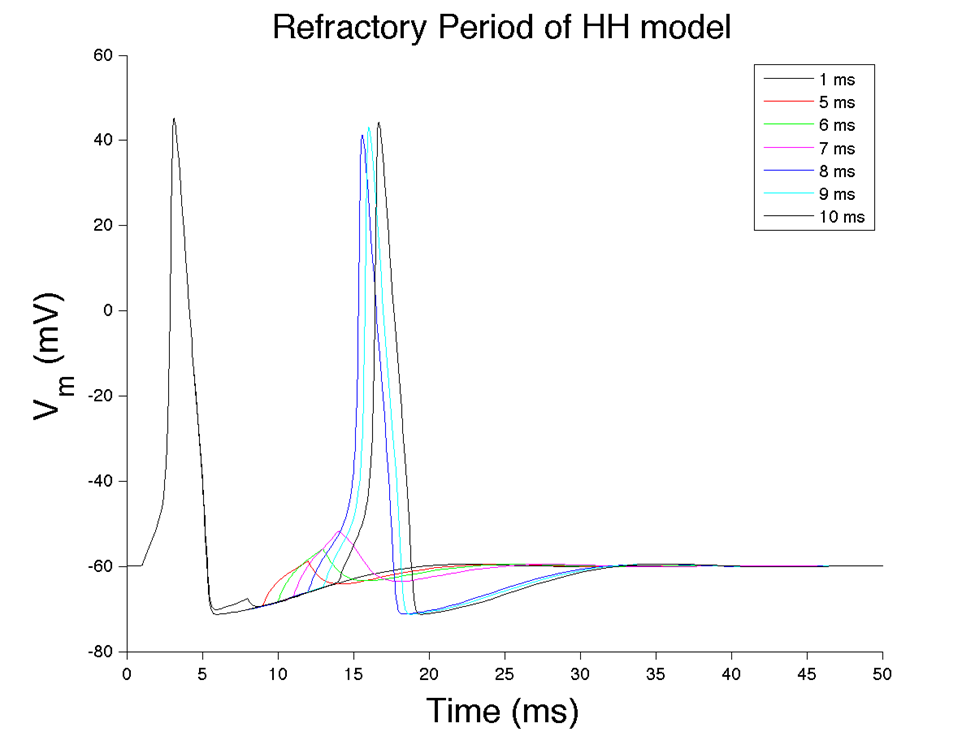

%Rose Long
% %% Hodgkin-Huxley model
%    
%    t                   time                    ms
%    V                   membrane potantial      mV
%    INa,IK,Il,Iion      ionic current           uA/cm2
%    Cm                  capacitance             uF/cm2

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% %% Step 1:  Define all constants
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Physical constants
global F R T RTF 
F = 96.5;                   % Faraday constant, coulombs/mmol
R = 8.314;                  % gas constant, J/K
T_celsius = 6.3;            % Temperature in celsius
T = 273 + T_celsius ;       % absolute temperature, K 

RTF = R*T/F ;

% default concentrations for squid axon in sea water - mmol/l
global Nao Ko Nai Ki 
Nao = 491 ;
Ko = 20 ;
Nai = 50 ;
Ki = 400 ;

% Cell constant
global Cm 
Cm = 1 ;                            % membrane capacitance, uF/cm^2;

% Maximum channel conductances -- mS/cm^2
global GNa GK Gl ENa EK El 
GNa = 120;
GK = 36;
Gl = 0.3;

% Nernst potentials -- mV
ENa = RTF*log(Nao/Nai);
EK = RTF*log(Ko/Ki);
El =  -49;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% %% Step 2:  Define simulation and stimulus parameters
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

tend =  50 ;              % end of simulation, ms

stimdelay = 1 ; %simulate base line ocnditions before drug/stimulus
stimdur = 3 ; %oringally 3 for part 1
stim_amp = -10 ; %originally=-4 %negative currents make voltage go down = cathodal ed Rose

%make a figure and hold it before the loop
figure; 
hold on;
%make a colors vector
colors = repmat('krgmbc',1,500)


times_between = [1 5 6 7 8 9 10]; %want to cycle through this. 

for iind = 1: length(times_between)
    
    time_between = times_between(iind);

    stim1_start = stimdelay ;
    stim1_end = stimdelay + stimdur ;
    stim2_start = stim1_end + time_between; %may have to define this after...
    stim2_end = stim2_start + stimdur ;

    % % % Intervals defined as follows
    % % % 1) t=0 zero to beginning of stimulus
    % % % 2) beginning to end of stimulus
    % % % 3) end of stimulus to end of simulation
    simints = 5 ;

    intervals(1,:) = [0,stim1_start] ;
    intervals(2,:) = [stim1_start,stim1_end] ;
    intervals(3,:) = [stim1_end,stim2_start] ;
    intervals(4,:) = [stim2_start,stim2_end];

    intervals(5,:) = [stim2_end,tend];
    %I stim is vector of how much current there is (at 3 different time
    %periods)
    Istim(1) = 0 ;
    Istim(2) = stim_amp ;
    Istim(3) = 0 ;
    Istim(4) = stim_amp ; %make the second one of the same amplitude
    Istim(5) = 0 ;

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % %% Step 3:  Set initial conditions
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    V = -60 ; %the voltage of membrane, if higher than Ena=55, na flows out (negative current) ed. Rose
    m = 0 ;
    h = 0.6 ;
    n = 0.3 ;

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % %% Step 4:  Loop through and solve model
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    statevar_i = [V,m,h,n] ;

    % % Simulate 60 seconds at rest before stimulus applied
    [post,posstatevars] = ode15s(@dydt_hh,[0,60000],statevar_i,[],0) ;
    statevar_i = posstatevars(end,:) ;

    t = 0 ;
    statevars = statevar_i ;
    for i=1:simints
      [post,posstatevars] = ode15s(@dydt_hh,intervals(i,:),statevar_i,[],Istim(i)) ; %empty bracket means no options; after: variable being sent to dydt_hh
      t = [t;post(2:end)] ;
      statevars = [statevars;posstatevars(2:end,:)] ;
      statevar_i = posstatevars(end,:) ; %new inital conditoins are the final conditions
    end

    %tkae all of columns and deal out to 4 differnt variables
    outputcell = num2cell(statevars,1) ;

    [V,m,h,n] = deal(outputcell{:}) ;

    gNa = GNa*m.^3.*h;
    INa = gNa.*(V-ENa);

    gK = GK*n.^4; 
    IK = gK.*(V-EK);

    Il = Gl*(V-El) ;
    Iion = INa + IK + Il ;

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % %% Step 5:  Plot or write output to files
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % here we plot the voltage trace for a vareity of time steps

    plot(t,V,colors(iind))
    set(gca,'TickDir','Out')
    xlabel('Time (ms)','FontSize',20)
    ylabel('V_m (mV)','FontSize',20)'
    
end
legend('1 ms','5 ms','6 ms', '7 ms', '8 ms' , '9 ms','10 ms')
title('Refractory Period of HH model','FontSize',20)
saveas(gcf,'ref_pd.tif')



%% this code plots voltage, ionic current, conductane and gating variable

figure
subplot(2,2,1)
plot(t,V)
set(gca,'TickDir','Out')
xlabel('time (ms)')
ylabel('V_m (mV)')
title(num2str(stim_amp)) %ed Rose

subplot(2,2,2)
hold on
plot(t,INa,'b')
plot(t,IK,'r')
plot(t,Il,'g')
set(gca,'TickDir','Out')
legend('I_N_a','I_K','I_L')
xlabel('time (ms)')
ylabel('Ionic current')
hold off

subplot(2,2,3)
hold on
plot(t,gNa,'b')
plot(t,gK,'r')
set(gca,'TickDir','Out')
legend('g_N_a','g_K')
xlabel('time (ms)')
ylabel('Conductances')

subplot(2,2,4)
hold on
plot(t,m,'b')
plot(t,h,'r')
plot(t,n,'g')
set(gca,'TickDir','Out')
legend('m','h','n')
xlabel('time (ms)')
ylabel('Gating variables')

hold off

%% putting more than one thing in the same figure
%put gating variabless in their own figure
figure
hold on
plot(t,m.*100,'b')
plot(t,h.*100,'r')
plot(t,n.*100,'g')
set(gca,'TickDir','Out')
legend('m','h','n')
xlabel('time (ms)')
ylabel('Gating variables')
plot(t,V)
hold on
title(num2str(stim_amp)) %ed Rose

% hold on
% plot(t,INa,'b--')
% plot(t,IK,'r--')
% plot(t,Il,'g--')
% set(gca,'TickDir','Out')
legend('m','h','n','voltage')
% xlabel('time (ms)')
% ylabel('Ionic current')

%% asdf

%hold off

%and voltages
%figure
plot(t,V)
set(gca,'TickDir','Out')
xlabel('time (ms)')
ylabel('V_m (mV)')
title(num2str(stim_amp)) %ed Rose





the differential function calculates the voltage and rate constants by updating ionic currents for every time

dydt_hh

%here is dydt function
function deriv = dydt_hh(t,statevar,Istim)

global F R T RTF ;
global Nao Ko Nai Ki ;
global Cm ;
global GNa GK Gl ENa EK El ;

nvariables = length(statevar) ;
statevarcell = num2cell(statevar) ;

[V,m,h,n] = deal(statevarcell{:}) ;


  %%% compute ionic currents
  gNa = GNa*m^3*h;
  INa = gNa*(V-ENa);

  gK = GK*n^4; 
  IK = gK*(V-EK);

  Il = Gl*(V-El) ;

  Iion = INa + IK + Il ;

  %% compute rate constants to update gates
  alphan = 0.01*(V+50)/(1-exp(-(V+50)/10));
  betan = 0.125*exp(-(V+60)/80);
  
  alpham = 0.1*(V+35)/(1-exp(-(V+35)/10));
  betam = 4*exp(-(V+60)/18) ;
  
  alphah = 0.07*exp(-(V+60)/20);
  betah = 1/(exp(-(V+30)/10)+1);
  
  dm = alpham - (alpham+betam)*m ;
  dh = alphah - (alphah+betah)*h ;
  dn = alphan - (alphan+betan)*n ;
  dV = -(Istim+Iion)/Cm; %Cm is memory capacitance
  
deriv = ...
  [dV;dm;dh;dn] ; %may not have to be column vector

return


